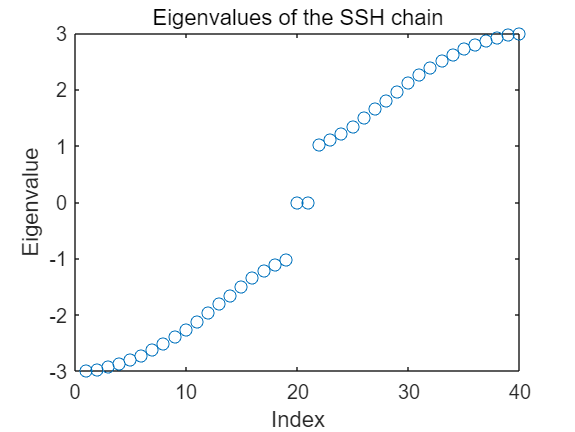

% Set the length of the SSH chain (2N)
N = 20;  % Chain length is 2N, here N = 20
t1 = 1;  % Intracell coupling
t2 = 2;  % Intercell coupling

% Create the Hamiltonian matrix
H = zeros(2*N);
for i = 1:2*N-1
    if mod(i,2) == 1
        H(i,i+1) = t1;
        H(i+1,i) = t1;
    else
        H(i,i+1) = t2;
        H(i+1,i) = t2;
    end
end

% Compute eigenvalues and eigenvectors
[eigenvectors, eigenvalues_matrix] = eig(H);
eigenvalues = diag(eigenvalues_matrix);

% Plot all eigenvalues
figure;
plot(1:2*N, eigenvalues, 'o');
title('Eigenvalues of the SSH chain');
xlabel('Index');
ylabel('Eigenvalue');

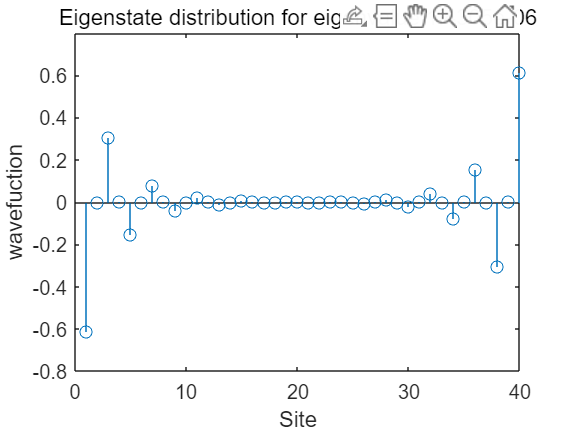


% Select an eigenvalue and its corresponding eigenvector
% Here we select the first eigenvalue's corresponding eigenvector
chosen_index = N+1 ;
chosen_eigenvector = eigenvectors(:, chosen_index);

% Plot the distribution of the eigenvector
figure;
stem(chosen_eigenvector);
title(['Eigenstate distribution for eigenvalue ', num2str(eigenvalues(chosen_index))]);
xlabel('Site');
ylabel('wavefuction');